# Hopper LQRtoSMC Control NonLinear system + Gravity with EKF + Noise

**1. Same as Hopper_LQR_Linear_EKF_v9.mlx**

**2. Trajectory: Up -> Hover -> Dowm**

**3. Enhanced Hopper dynamic: T*u_dot + a*u = u_app**

clc; clear all; close all;

## Parameters

SimulinkOpen = false;
disturbOn = false;
GravityCompansation = true;
Euler_Angles = true;
RollUp = false;
DiagInertia = true;

## Generate trajectory (Earth Frame)

deg = deg2rad(1);
% run("Generate_trajectory.m");     % Reference trajectory
run("Geometry_Levers_1.m");         % Levers position and orientation
run("mass_config_v1.m");            % Hopper's Moment of Inertia from Solidworks
run("Hopper\Guidance\guidance_params.m")   % guidance parameters
geometry

geometry =          0         0         0         0         0         0         0         0         0
    0.3609    0.3050         0  -45.0000   90.0000         0   45.0000   90.0000         0
    0.3609    0.3050         0   45.0000   90.0000         0  -45.0000   90.0000         0
    0.3609    0.3050         0  135.0000   90.0000         0 -135.0000   90.0000         0
    0.3609    0.3050         0 -135.0000   90.0000         0  135.0000   90.0000         0
    0.2717    0.2739         0         0         0         0   90.0000   90.0000         0
    0.2717    0.2739         0         0         0         0         0   90.0000         0
    0.2717    0.2739         0         0         0         0  -90.0000   90.0000         0
    0.2717    0.2739         0         0         0         0  180.0000   90.0000         0


% Real and Model Inertia
RealInertia = Tensors;
if DiagInertia
    for i=1:length(Tensors)
        Tensors(:,:, i) = DiagTensorInertia(Tensors(:,:, i));
    end
end

if RollUp
    geometry(2:5, 2) = ones(4,1) * rcgs(1, 1);
end

%% Gravity 
g = 9.8065;                        % G-Force value
Lg = 1 / g;                        % Inverse G-force value
G = [-g; 0; 0];                   % G-Force vector in Earth Frame

%% Mass
m_max = mass(1);                    % maximum mass
m_dry = mass(end);                  % minimum mass
fuel_capacity = 4;                  % Full fuel capacity
m_fuel = 4;                         % mass of fuel
m_full = m_dry + fuel_capacity;     % mass of filled hopper
m = m_dry + m_fuel;                 % current or initial mass

%% Inertia
% Central tensor inertia moment 
Js = tensor_interpolation(m, mass, Tensors);
% Tensor of Inertia for dry hopper
Js0 = tensor_interpolation(m_dry, mass, Tensors);

% jet rotor mass inertia
Jrotx = 9e-3; Jroty = 1e-2; Jrotz = 1e-2;
Jrot = diag([Jrotx, Jroty, Jrotz]);
params_rotor = [Jrotx, Jroty, Jrotz];

% Tensor Inertia Components
% Jxx = Js(1,1); Jyy = Js(2,2); Jzz = Js(3,3);

Thrust = 45;                                % Maximum Thrust, kg
mdot_max = 17.7 * 1e-3 * Tjet / Thrust;     % kg/s, max consumption
Fmax = Tjet * g;                           % N, 

%% Frequency 
n_max = 90000;               % rpm
wn_max = pi * n_max / 30;    % rad/s

beta = mdot_max / Fmax;     % mass consumption to thrust ratio
gamma = wn_max / Fmax;      % frequency to thrust ratio

rho = 1.2754;               % air density

% Damphers
c_v = 0.1;      % Linear
c_w = 0.01;     % Angular

% Damping matrix
Cv = diag([c_v, c_v, c_v]);
Cw = diag([c_w, c_w, c_w]);

% Center of mass
r_cg = rcgs(1, :);

[Hf, Hm] = ComponentForForces(geometry, rcgs(1,:))

Hf =     1.0000    0.0000    0.0000    0.0000    0.0000    1.0000    1.0000    1.0000    1.0000
         0    0.7071    0.7071   -0.7071   -0.7071         0         0         0         0
         0   -0.7071    0.7071    0.7071   -0.7071         0         0         0         0


Hm =          0   -0.3606    0.3585   -0.3611    0.3632         0         0         0         0
    0.0015   -0.2560    0.2560    0.2560   -0.2560    0.2732    0.0015   -0.2702    0.0015
    0.0018   -0.2560   -0.2560    0.2560    0.2560    0.0018   -0.2699    0.0018    0.2735


%% Remove unnessary data
clear c_v c_w Thrust mdot_max Fmax wn_max Fmax;
% clear Jxx Jyy Jzz;
clear Jrotx Jroty Jrotz;

## Initial conditions

pos0 = [0; 0; 0];                       % position
vel0 = [0; 0; 0];                       % velocity
eul0 = [0; 0; 0];                   % attitude [roll, pitch, yaw]
rot0 = [0; 0; 0];                       % angular velocity
% General State vector
xIC = [pos0; vel0; eul0; rot0];       % initial condition for Simulink model

%               dFx  dFy  dFz dMx dMy dMz
disturbances = [0;    0;   0;  0;  0;  0];      % either constants or functions
k_quat = 1;
%% For Jdot calculation
Jo = DiagTensorInertia(Tensors(:,:, 1));
Jf = DiagTensorInertia(Tensors(:,:, end));
mo = mass(1);
mf = mass(end);
Jdot_coeff = (Jo - Jf) / (mo - mf);
gc = 1;                                 %GravityCompansation;

%% New transtition matrices
syms phi theta psi;
E2W([phi theta psi])

$$ans = \left(\begin{array}{ccc} 1 & \frac{\sin\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)}\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$

N2B([phi theta psi])

$$ans = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & -\sin\left(\theta \right)\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

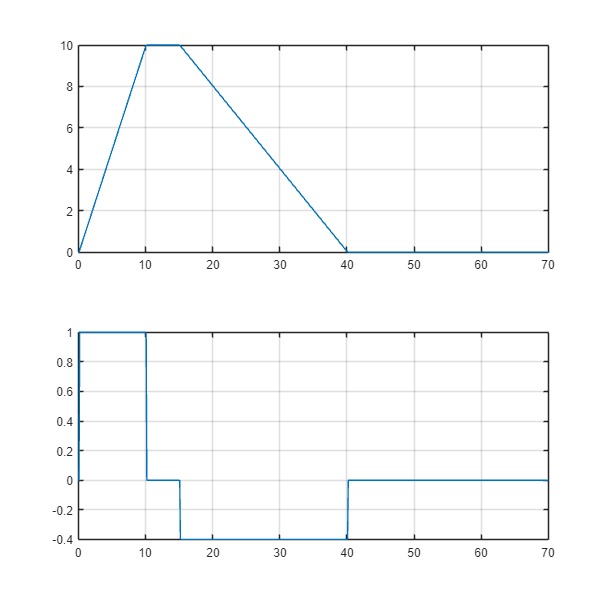

%% Reference trajectory check
Tf0 = 70; dt0 = 0.1;
tu = 0:0.1:Tf0;
N = Tf0 / dt0;
y = zeros(12,N+1);
for i=1:N
    y(:, i+1) = reference(y(:,i), guide_params, tu(i), 10, dt0);
end

figure;
subplot(2,1,1);
plot(tu, y(1,:)); grid;

subplot(2,1,2);
plot(tu, y(4,:)); grid;

## Define parameters

% Real Object Structure
params = struct();
params.Inertia = RealInertia;
params.mass = mass;
params.rcgs = rcgs;
params.Jrot = Jrot;
params.Cv = Cv;
params.Cw = Cw;
params.Hf = Hf;
params.Hm = Hm;
params.Jdot_mlt = (Js - Js0) / (mass(1) - mass(end));
params.k_quat = k_quat;
params.m = m;
params.fuel = m_fuel;
params.g = g;
params.G = G;
params.gc = gc;
params.rho = rho;
params.beta = beta;
params.gamma = gamma;
params.d = disturbances;
% params.Gain = K_lqrq;
params.geom = geometry;
params.Jo = RealInertia(:,:,1);
params.Jdot = zeros(3);
params.grav_on = 0;
params.w = [0.02, 0.02, 0.02, 1.5, 1.5, 1.5, 1.5, 1.5, 1.5];

#### Model Structure

modelparams = struct();
modelparams.Inertia = Tensors;
modelparams.mass = mass;
modelparams.rcgs = rcgs;
modelparams.Jrot = Jrot;
modelparams.Cv = Cv;
modelparams.Cw = Cw;
modelparams.Hf = Hf;
modelparams.Hm = Hm;
modelparams.Jdot_mlt = (Js - Js0) / (mass(1) - mass(end));
modelparams.k_quat = k_quat;
modelparams.m = m;
modelparams.fuel = m_fuel;
modelparams.g = g;
modelparams.G = G;
modelparams.gc = gc;
modelparams.rho = rho;
modelparams.beta = beta;
modelparams.gamma = gamma;
modelparams.d = disturbances;
% modelparams.Gain = K_lqrq;
modelparams.geom = geometry;
modelparams.Jo = Tensors(:,:,1);
modelparams.Jdot = zeros(3);
modelparams.grav_on = 0;


% parameters = [Tensor2Vector(Js)'; Cv(1,1); Cv(2,2); Cv(3,3); Cw(1,1); Cw(2,2); Cw(3,3); gg; beta; gamma; rho; diag(Jdot_coeff); k_quat; gc; m];
clear Jo Jf Js Js0 mo mf Jdot_coeff gc k_quat disturbances Cv Cw sys_poles Ps Gcl Qs Rs;
clear x0 y0 ref_yaw ref_pitch ref_roll ref_eul init_yaw init_pitch init_roll dtau Tf;
clear geometry Hf Hm;

w = [0.01, 0.01, 0.01, 1., 1., 1., 1., 1., 1.];
geom2 = disturb_geom(params.geom, 0.05);
new_params = variate_geom_params(params, w);
params.geom

ans =          0         0         0         0         0         0         0         0         0
    0.3609    0.3050         0  -45.0000   90.0000         0   45.0000   90.0000         0
    0.3609    0.3050         0   45.0000   90.0000         0  -45.0000   90.0000         0
    0.3609    0.3050         0  135.0000   90.0000         0 -135.0000   90.0000         0
    0.3609    0.3050         0 -135.0000   90.0000         0  135.0000   90.0000         0
    0.2717    0.2739         0         0         0         0   90.0000   90.0000         0
    0.2717    0.2739         0         0         0         0         0   90.0000         0
    0.2717    0.2739         0         0         0         0  -90.0000   90.0000         0
    0.2717    0.2739         0         0         0         0  180.0000   90.0000         0


new_params.geom

ans =    -0.0082   -0.0087   -0.0039   -0.1355   -0.2608    0.1807    0.2370   -0.5761    0.4938
    0.3603    0.3098    0.0051  -44.9312   90.5945   -0.3125   44.7342   89.2103   -0.7127
    0.3536    0.2951   -0.0084   44.2952   89.9466    0.7533  -44.6951   90.3408    0.0749
    0.3559    0.2975    0.0097  134.6512   89.5508    0.1937 -134.8483   89.8108   -0.1124
    0.3613    0.3062   -0.0079 -134.1383   90.9713    0.0494  135.4508   89.6805   -0.4453
    0.2644    0.2721   -0.0000    0.9984   -0.5792    0.4570   90.8238   90.5191    0.3393
    0.2779    0.2769   -0.0053    0.5914   -0.5261    0.5183   -0.3586   89.2112    0.1995
    0.2761    0.2755   -0.0060    0.5477    0.0186    0.8544  -89.2707   90.0511    0.8961
    0.2721    0.2706    0.0013    0.4660   -0.5638    0.1671  179.7352   89.2355    0.9809


geom2

geom2 =          0         0         0         0         0         0         0         0         0
    0.3786    0.2980         0  -43.7084   88.5280         0   47.1135   88.4974         0
    0.3573    0.2994         0   46.1602   89.9030         0  -46.5204   88.1249         0
    0.3751    0.2898         0  136.5876   86.8598         0 -139.9579   86.0833         0
    0.3707    0.3160         0 -131.4329   87.3506         0  131.4133   92.1747         0
    0.2703    0.2782         0         0         0         0   91.5501   89.6966         0
    0.2794    0.2671         0         0         0         0         0   93.3323         0
    0.2686    0.2668         0         0         0         0  -93.0086   88.0933         0
    0.2790    0.2836         0         0         0         0  171.8791   93.0320         0


## Linear System

dt = 0.01;
nx = 13; ny = 12; nu = 9; 
uIC = zeros(nu,1);
[A, B] = jacobian_HopperODE(xIC, uIC, modelparams)

A =          0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0   -0.0039         0         0         0         0         0         0         0         0
         0         0         0         0   -0.0039         0         0         0         0         0         0         0
         0         0         0         0         0   -0.0039         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0        

B =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    0.0390    0.0000    0.0000    0.0000    0.0000    0.0390    0.0390    0.0390    0.0390
         0    0.0276    0.0276   -0.0276   -0.0276         0         0         0         0
         0   -0.0276    0.0276    0.0276   -0.0276         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0   -0.5544    0.5511   -0.5551    0.5584         0         0         0         0


modelparams.grav_on = 1;
[A2, B2] = jacobian_HopperODE(xIC, uIC, modelparams)

A2 =          0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0   -0.0039         0         0         0         0         0         0         0         0
         0         0         0         0   -0.0039         0         0         0    9.8065         0         0         0
         0         0         0         0         0   -0.0039         0   -9.8065         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0       

B2 =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    0.0390    0.0000    0.0000    0.0000    0.0000    0.0390    0.0390    0.0390    0.0390
         0    0.0276    0.0276   -0.0276   -0.0276         0         0         0         0
         0   -0.0276    0.0276    0.0276   -0.0276         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0   -0.5544    0.5511   -0.5551    0.5584         0         0         0         0


modelparams.grav_on = 0;
% Discrete system Method 1: Exact discretization (matrix exponential)
C = eye(ny); D = zeros(ny,nu);
sysc = ss(A2, B2, C, D);  % Create continuous system
sysd = c2d(sysc, dt, 'zoh');  % Zero-order hold
modelparams.plant.A = A2;
modelparams.plant.B = B2;
modelparams.plant.C = C;
modelparams.plant.D = D;
modelparams.plant.Ad = sysd.A;
modelparams.plant.Bd = sysd.B;
modelparams.plant.Cd = sysd.C;
modelparams.plant.Dd = sysd.D;

## LQR

Qs = diag([ ...
    100, 100, 100, ...                 % Position
    50, 50, 50 ...                  % Linear velocity    
    100, 100, 100, ...                 % Euler's Angles
    50, 50, 50]); % ...             % Angular velocity
%% Control Penalty
Rs = diag([ ...
    0.005, ...                      % Jet
    0.05, 0.05, 0.05, 0.05, ...     % Roll Forces
    0.01, 0.01, 0.01, 0.01]);       % Pitch and Roll
K_lqr = lqrd(A, B, Qs, Rs, dt)

K_lqr =    78.4550    0.0495   -0.0412   66.4280    0.0377   -0.0313    0.0000    0.3961    0.4763    0.0000    0.2831    0.3405
    0.0962   19.5833  -19.7071    0.0732   23.2590  -23.4088  -18.8013   -9.4473   -9.3997  -13.9103   -6.8818   -6.8469
    0.0088   19.6959   19.7069    0.0067   23.3951   23.4086   18.7015    9.4476   -9.4429   13.8391    6.8820   -6.8786
   -0.0962  -19.6961   19.5715   -0.0732  -23.3953   23.2449  -18.8215    9.3957    9.4426  -13.9248    6.8439    6.8785
   -0.0088  -19.5831  -19.5713   -0.0067  -23.2588  -23.2447   18.9213   -9.3960    9.4000   13.9960   -6.8441    6.8471
   38.8765    0.0246  -31.8786   32.8795    0.0187  -40.2184    0.0235   59.4362    0.2371    0.0173   48.2179    0.1694
   39.6496  -31.8312   -0.0207   33.6163  -40.1823   -0.0158    0.0196    0.1992  -59.0025    0.0144    0.1424  -47.9111
   39.5785    0.0249   31.8374   33.5485    0.0189   40.1870   -0.0235  -59.0401    0.2393   -0.0173  -47.9348    0.1710
   38.8054   31.8807   -

[K_lqr2, P2, E] = lqrd(A2, B2, Qs, Rs, dt)

K_lqr2 =    78.4531    0.4435   -0.3688   66.4262    0.5224   -0.4344    0.0000    1.7463    2.1001    0.0000    0.3987    0.4795
    0.1250    9.1620   -9.2291    0.1152    7.1519   -7.2100  -18.8011   -5.3750   -5.4022  -13.9100   -8.0459   -8.0083
    0.0115    9.2238    9.2287    0.0106    7.2054    7.2095   18.6990    5.3766   -5.3768   13.8352    8.0462   -8.0431
   -0.1250   -9.2243    9.1542   -0.1152   -7.2060    7.1451  -18.8218    5.4074    5.3752  -13.9251    8.0044    8.0428
   -0.0115   -9.1615   -9.1537   -0.0106   -7.1514   -7.1446   18.9239   -5.4090    5.4038   13.9999   -8.0047    8.0086
   38.7739    0.2204  -61.6124   32.7924    0.2596  -72.5961    0.0281  283.3643    1.0434    0.0191   64.9002    0.2382
   39.7709  -61.2048   -0.1858   33.7190  -72.1187   -0.2188    0.0233    0.8798 -281.4688    0.0159    0.2009  -64.4752
   39.6793    0.2231   61.2435   33.6338    0.2628   72.1617   -0.0281 -281.6179    1.0567   -0.0191  -64.5015    0.2413
   38.6822   61.6483   

P2 =    84.2134   -0.0536    0.0445   10.4591   -0.0624    0.0519   -0.0000   -0.1982   -0.2385   -0.0000   -0.0458   -0.0551
   -0.0536  111.3320    0.0002   -0.0501   38.1591    0.0002    0.0025   -0.0008   73.6726    0.0028   -0.0001    6.4312
    0.0445    0.0002  111.3305    0.0416    0.0002   38.1569    0.0030  -73.6616    0.0008    0.0034   -6.4278    0.0001
   10.4591   -0.0501    0.0416    8.8030   -0.0590    0.0491   -0.0000   -0.1849   -0.2225   -0.0000   -0.0425   -0.0512
   -0.0624   38.1591    0.0002   -0.0590   38.1346    0.0003    0.0017   -0.0009   87.0077    0.0024   -0.0002    7.5789
    0.0519    0.0002   38.1569    0.0491    0.0003   38.1318    0.0021  -86.9936    0.0009    0.0029   -7.5747    0.0002
   -0.0000    0.0025    0.0030   -0.0000    0.0017    0.0021   73.5214    0.0040   -0.0034    2.0265    0.0028   -0.0023
   -0.1982   -0.0008  -73.6616   -0.1849   -0.0009  -86.9936    0.0040  350.7605   -0.0035   -0.0014   29.6175   -0.0007
   -0.2385   73.6726    0.0

E =    0.9860 + 0.0000i
   0.9860 + 0.0000i
   0.9859 + 0.0000i
   0.9856 + 0.0000i
   0.9760 + 0.0202i
   0.9760 - 0.0202i
   0.9760 + 0.0202i
   0.9760 - 0.0202i
   0.9361 + 0.0000i
   0.8897 + 0.0000i


Cs_att  = lqrd(A2(7:end,7:end), B2(7:end,2:end), Qs(7:end,7:end), Rs(2:end, 2:end), dt)

Cs_att =   -18.8009  -10.7609  -10.7053  -13.9098   -8.5265   -8.4816
   18.6968   10.7614  -10.7565   13.8334    8.5269   -8.5234
  -18.8220   10.7000   10.7560  -13.9253    8.4768    8.5229
   18.9261  -10.7005   10.7058   14.0016   -8.4773    8.4821
    0.0278   57.2759    0.3839    0.0226   45.3794    0.3041
    0.0231    0.3225  -56.5707    0.0188    0.2556  -44.8230
   -0.0278  -56.6345    0.3875   -0.0226  -44.8712    0.3071
   -0.0231    0.3189   57.3421   -0.0188    0.2526   45.4342


%% Attitude-only actuator-space LQR (use actuators 2:9 only)
A_att = A2(7:12, 7:12);      % [roll pitch yaw wx wy wz]
B_att = B2(7:12, 2:9);       % only attitude propellers
dtau =0.01;
Q_att = diag([ ...
    40, 40, 20, ...   % roll, pitch, yaw
    8,  8,  4]);      % wx, wy, wz

R_att = diag([ ...
    0.4, 0.4, 0.4, 0.4, ...   % roll props 2:5
    0.8, 0.8, 0.8, 0.8]);     % pitch/yaw props 6:9

K_att_u = lqrd(A_att, B_att, Q_att, R_att, dtau)

K_att_u =    -4.8311   -4.3795   -3.0856   -2.9968   -4.6650   -3.8009
    4.8050    4.3795   -3.1020    2.9825    4.6650   -3.8227
   -4.8352    4.3530    3.1020   -2.9988    4.6340    3.8226
    4.8614   -4.3530    3.0856    3.0131   -4.6341    3.8010
    0.0012    2.3305    0.0111    0.0014    2.4817    0.0137
    0.0008    0.0131   -1.6310    0.0010    0.0139   -2.0095
   -0.0012   -2.3044    0.0111   -0.0014   -2.4539    0.0137
   -0.0008    0.0130    1.6532   -0.0010    0.0139    2.0369


params.ctrl.K_att_u = K_att_u;
params.ctrl.g = g;
modelparams.ctrl = params.ctrl;

## EKF

% Nav Noise
pos_dev = 0.05;
vel_dev = 0.02;
eul_dev = 0.5 * deg2rad(1.);   % Euler's angle measurement deviation
rot_dev = 0.5 * deg2rad(1.);    % Angular velocity measurement deviation
w_ymeas = [pos_dev, pos_dev, pos_dev, ...
    vel_dev, vel_dev, vel_dev, ...
    eul_dev, eul_dev,eul_dev, ...
    rot_dev,rot_dev,rot_dev]';
% Model disturbances
w_max = 1e-2;


Q = 0.5*diag([ ...
    1e-4*ones(3,1);    % position
    5e-4*ones(3,1);    % velocity
    1e-5*ones(3,1);    % angles
    1e-4*ones(3,1)     % rates
  ]);        % Process noise covariance

R = diag([ ...
    5e-3*ones(3,1);   % position (GPS-like)
    1e-2*ones(3,1);   % velocity
    5e-4*ones(3,1);   % angles (IMU good!)
    1e-3*ones(3,1)    % rates
   ]);        % Measurement noise covariance

%% EKF parameters
params.ekf.Q = Q;
params.ekf.R = R;
params.ekf.C = C;
%% EKF parameters
params.ekf.Qd = Q;
params.ekf.Rd = R;
params.ekf.Cd = C;
clear Q R;

% Control constraints
umax = params.g * [40; 3; 3; 3; 3; 3; 3; 3; 3] * 0.9;
umin = zeros(nu,1);
smax = params.g * [40; 3; 3; 3; 3; 3; 3; 3; 3] * 0.8;
smin = -smax;


alpha = 12;
W = diag([alpha; ones(8,1)]);
% F2U = W * params.Hf' * inv(params.Hf * W * params.Hf');
% F2U (params.Hf * W * params.Hf' \ (W * params.Hf')')'
F2U = ((params.Hf * W * params.Hf') \ (params.Hf * W))';


params.ctrl.ulim = zeros(nu, 2);
params.ctrl.slim = zeros(nu, 2);
kT = 1; % The more coefficient the slower reaaction
params.ctrl.T = kT * [0.5; 0.02 * ones(nu-1,1)]; % for Ts=0.01 T should be Ts / 5
params.ctrl.t1 = 1 * ones(nu,1);
params.ctrl.alpha = 12;
params.ctrl.Q = Qs;
params.ctrl.R = Rs;
params.ctrl.F2U = F2U;
for i = 1:nu
    params.ctrl.ulim(i, :) = [umin(i), umax(i)];
    params.ctrl.slim(i, :) = [smin(i), smax(i)];
end

% Guidance parameters
PredictionHorizon = 1;
tstop = 10;

% Tunable coefficients
%% Cascade VTOL controller parameters

% Outer position loop gains
params.ctrl.Kp_pos = diag([0.8 0.8 1.2]);
params.ctrl.Kd_pos = diag([1.2 1.2 1.8]);

% Desired yaw from reference
params.ctrl.use_ref_yaw = true;

% Attitude/rate sliding surface (inner loop)
% % state_att = [roll pitch yaw wx wy wz]
% params.ctrl.Cs_att = [ ...
%     1.2 0   0   0.4 0   0;
%     0   1.2 0   0   0.4 0;
%     0   0   0.8 0   0   0.25];

params.ctrl.Cs_att = Cs_att;

params.ctrl.K1_att = [0.5; 0.5; 0.3];
params.ctrl.K2_att = [0.12; 0.12; 0.08];
params.ctrl.phi_att = [0.25; 0.25; 0.35];

params.ctrl.alpha_s_att = 0.4;
params.ctrl.int_thresh_att = [0.08; 0.08; 0.12];

% Jet thrust loop gains
params.ctrl.Kp_thrust = 0.08;
params.ctrl.Kd_thrust = 0.12;

% Jet command smoothing / ramp
params.ctrl.alpha_jet_cmd = 0.15;

modelparams.ctrl = params.ctrl;
% coeffs = [K11; K12; K13; K21; K22; K23; phi1; phi2; phi3];
% [K1, K2, phi] = sta_coeffs_distrib(coeffs);
% [K1, K2, phi]

% Reference
xRef = [10; 0; 0;  1;  0;  0; 0; pi/2; 0; 0; 0; 0];
Cmeas = eye(nx);
C1 = Cmeas(1:ny, :);   % We don't estimate mass and don't use mass for reference
params.C = Cmeas;
params.C1 = C1;

% Simulation parameters
Ts = dt;
T = 5;        % VTOL
tspan = 0:Ts:T;
N = T/Ts;

%% SMC parameters
% Option: Slow adaptation. Gains to tune: phi, gamma, K0, k2
% Cs = diag([10 10 10 5 5 5 8 8 8 2 2 2]);  % Sliding surface gain
Cs = K_lqr;                      %[1 0 0 0; 0 0 1 0];  % Sliding surface design
params.ctrl.Cs = Cs;
params.ctrl.Cs2 = K_lqr2;
params.ctrl.Kmin = 0.1;
params.ctrl.Kmax = 100;
params.ctrl.dz2min = -100;
params.ctrl.dz2max = 100;
params.ctrl.z2min = -50;
params.ctrl.z2max = 50;
% params.ctrl.z2decay = 0.98;
% params.ctrl.K1 = K1;
% params.ctrl.K2 = K2;
% params.ctrl.phi = phi;
params.ctrl.dt = dt;


% --- EKF/STA alignment parameters ---
params.ctrl.Wstate = diag([ ...
    1.0 1.0 1.0 ...
    0.10 0.10 0.10 ...
    1.0 1.0 1.0 ...
    0.10 0.10 0.10]);

params.ctrl.alpha_v = 0.15;      % EKF velocity smoothing
params.ctrl.alpha_w = 0.15;      % EKF angular-rate smoothing
params.ctrl.alpha_s = 0.20;      % sliding surface smoothing

params.ctrl.int_thresh = 0.05 * ones(nu,1);   % initial integral deadzone


%% bias adaptivity
params.ctrl.trim_ki   = diag([0.03, 0.05, 0.05]);
params.ctrl.trim_leak = 0.05;
params.ctrl.trim_umax = 0.02 * ones(8,1);


modelparams.ctrl = params.ctrl;
modelparams.ekf = params.ekf;
params.plant = modelparams.plant;
z2 = zeros(nu,1);       % Initialize STA internal state
s = zeros(nu,1);

% u_prev = zeros(nu,1);
u_dot_max = 50;         % Change this based on actuator rate [N/s]

% Initial condiditions
y0 = xIC;
x0 = [y0; params.m];
xhat = y0 + 0.01*(2*rand(ny, 1)-1);          % EKF estimated initial state
P = eye(ny) * 0.1;                           % Initial error covariance

% Store
x_hist = zeros(nx, N+1);
xhat_hist = zeros(ny, N+1);
xref_hist = zeros(ny, N+1);
u_hist = zeros(nu, N+1);
u_cmd_hist = zeros(nu, N+1);
% u_hist1 = zeros(nu, N);
% u_hist2 = zeros(nu, N);
err_hist = zeros(ny, N+1);
K_hist = zeros(nu, N+1);
s_hist = zeros(nu, N+1);
z2_hist = zeros(nu, N+1);


% Initialize Logs
x_hist(:, 1) = x0;
xhat_hist(:, 1) = xhat;
xref_hist(:, 1) = x_ref;
z2_hist(:, 1) = z2;
% K_hist(:, 1) = K;
err_hist(:,1) = xhat - xref_hist(:, 1);

% Init STA state
% Init cascade controller state
sta_state.int_sig_s = zeros(3,1);     % only roll/pitch/yaw channels
sta_state.s = zeros(3,1);
sta_state.s_filt = zeros(3,1);

sta_state.jet_cmd_filt = 0;
sta_state.last_T_cmd = 0;

x_ref = zeros(12,1);
x_ref(8) = deg2rad(0);      % desired pitch
x_ref(7) = deg2rad(0);         % roll
x_ref(9) = deg2rad(0);         % yaw
x_ref(10:12) = 0;               % rates

trim_state.M_bias_hat = zeros(3,1);
trim_state.u_trim = zeros(8,1);
u_trim_hist = zeros(8, N+1);
M_bias_hist = zeros(3, N+1);
% xhat_new = xhat; P_new = P;
% Simulation loop
for k = 1:N
    t = tspan(k+1);
    % x_ref = ref_traj_generator(t, Ts, PredictionHorizon, tstop, )';
    % x_ref = reference(x_ref, guide_params, t, tstop, dt);
    % x_ref = xRef;
    x_true = x_hist(:, k);
    xhat = xhat_hist(:, k);
    u_true = u_hist(:, k);
    
    %     trim_state = update_trim_estimator(trim_state, [xhat; x_true(13)], x_ref, params);
    % [u_cmd, dbg] = vtol_attitude_only_actuator_lqr_ctrl([xhat; x_true(13)], x_ref, params, trim_state);
    [u_cmd, dbg] = vtol_attitude_only_actuator_lqr_ctrl([xhat; x_true(13)], x_ref, params);
    % [u_cmd, dbg] = vtol_attitude_only_actuator_lqr_ctrl([xhat; x_true(13)], x_ref, params);
    e = dbg.err_r;


    w = w_max * (2 * rand(nx, 1) - 1); % 
    xdot_g = @(t, x) NL_HopperDyn(x, u_cmd, params) + w;
    [~, xSol] = ode45(xdot_g, [0 Ts], x_true);
    x_true = xSol(end, 1:nx)';
    %     u_true = xSol(end, nx+1:end)';
    
    % Measurement (with noise). Read sensors
    y_meas = x_true(1:ny) + w_ymeas .* (2 * rand(ny, 1) - 1);

    % EKF Prediction
    [xhat, P] = ekf_d(xhat, P, u_cmd, y_meas, modelparams.ekf, modelparams);

    x_hist(:, k+1) = x_true;
    xhat_hist(:, k+1) = xhat;
    xref_hist(:, k+1) = x_ref;
    err_hist(7:12, k+1) = e;
    
    % Store STA State
    s_hist(1:3, k+1) = sta_state.s;
    z2_hist(1:3, k+1) = sta_state.int_sig_s;
    % Store control
    u_hist(:, k+1) = u_true;
    u_cmd_hist(:, k+1) = u_cmd;
    % u_trim_hist(:, k+1) = trim_state.u_trim;
    M_bias_hist(:, k+1) = dbg.M_jet;
end

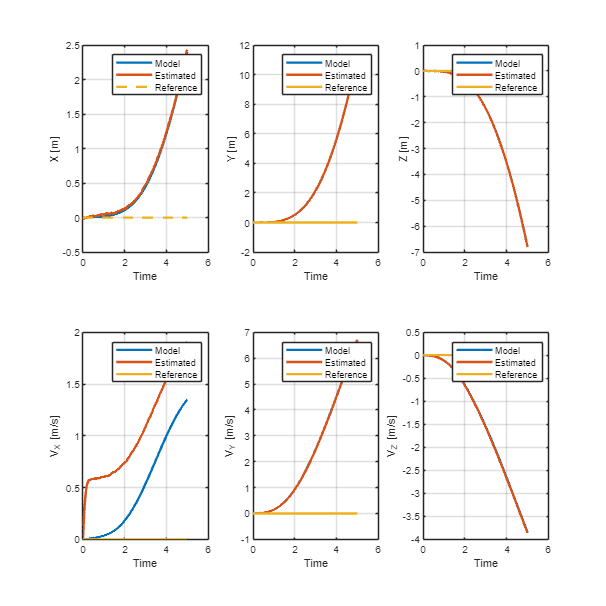

%% Plot
figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');
% Plot positions
% X
subplot(2,3,1); 
title('Pos X');
plot(tspan, x_hist(1,:), tspan, xhat_hist(1,:), tspan, xref_hist(1,:), '--');  grid;
xlabel('Time');
ylabel('X [m]');
legend('Model', 'Estimated', 'Reference');

% Y
subplot(2,3,2); 
title('Pos Y');
plot(tspan, x_hist(2,:), tspan, xhat_hist(2,:), tspan, xref_hist(2,:));  grid;
xlabel('Time');
ylabel('Y [m]');
legend('Model', 'Estimated', 'Reference');

% Z
subplot(2,3,3); 
title('Pos Z');
plot(tspan, x_hist(3,:), tspan, xhat_hist(3,:), tspan, xref_hist(3,:));  grid;
xlabel('Time');
ylabel('Z [m]');
legend('Model', 'Estimated', 'Reference');

% Vx
subplot(2,3,4); 
title('Vel X');
plot(tspan, x_hist(4,:), tspan, xhat_hist(4,:), tspan, xref_hist(4,:));  grid;
xlabel('Time');
ylabel('V_X [m/s]');
legend('Model', 'Estimated', 'Reference');


% Vy
subplot(2,3,5); 
title('Vel Y');
plot(tspan, x_hist(5,:), tspan, xhat_hist(5,:), tspan, xref_hist(5,:));  grid;
xlabel('Time');
ylabel('V_Y [m/s]');
legend('Model', 'Estimated', 'Reference');


% Vz
subplot(2,3,6); 
title('Vel Z');
plot(tspan, x_hist(6,:), tspan, xhat_hist(6,:), tspan, xref_hist(6,:));  grid;
xlabel('Time');
ylabel('V_Z [m/s]');
legend('Model', 'Estimated', 'Reference');


% set(groot, 'DefaultFigurePosition', [2000, 200, 200, 2000]);
% set(groot, 'DefaultFigurePosition', 'factory');    % use to reset size
set(findall(gcf,'type','line'),'linewidth', 2);

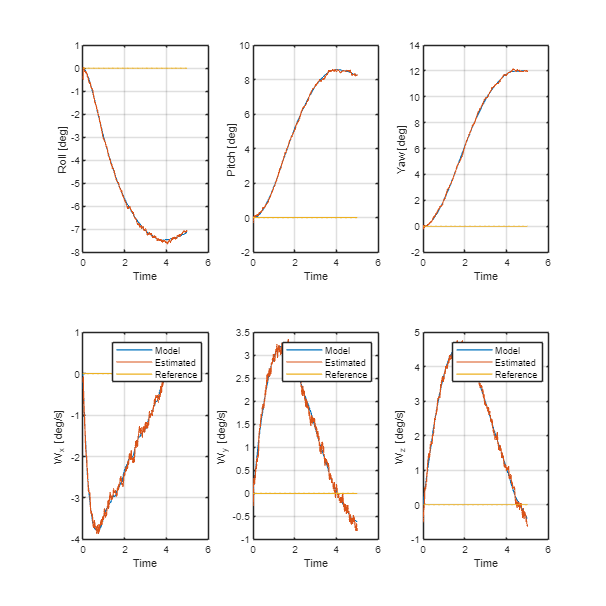

%% Plot angles
figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

% Roll
subplot(2,3,1); 
title('Roll');
plot(tspan, rad2deg(x_hist(7,:)), tspan, rad2deg(xhat_hist(7,:)), tspan, rad2deg(xref_hist(7,:)));  grid;
xlabel('Time');
ylabel('Roll [deg]');
% legend('Model', 'Estimated', 'Reference');

% Pitch
subplot(2,3,2); 
title('Pitch');
plot(tspan, rad2deg(x_hist(8,:)), tspan, rad2deg(xhat_hist(8,:)), tspan, rad2deg(xref_hist(8,:)));  grid;
xlabel('Time');
ylabel('Pitch [deg]');
% legend('Model', 'Estimated', 'Reference');

% Yaw
subplot(2,3,3); 
title('Yaw');
plot(tspan, rad2deg(x_hist(9,:)), tspan, rad2deg(xhat_hist(9,:)), tspan, rad2deg(xref_hist(9,:)));  grid;
xlabel('Time');
ylabel('Yaw [deg]');
% legend('Model', 'Estimated', 'Reference');

% Wx
subplot(2,3,4); 
title('Rot. X');
plot(tspan, rad2deg(x_hist(10,:)), tspan, rad2deg(xhat_hist(10,:)), tspan, rad2deg(xref_hist(10,:)));  grid;
xlabel('Time');
ylabel('W_x [deg/s]');
legend('Model', 'Estimated', 'Reference');

% Wy
subplot(2,3,5); 
title('Rot. Y');
plot(tspan, rad2deg(x_hist(11,:)), tspan, rad2deg(xhat_hist(11,:)), tspan, rad2deg(xref_hist(11,:)));  grid;
xlabel('Time');
ylabel('W_y [deg/s]');
legend('Model', 'Estimated', 'Reference');


% Wz
subplot(2,3,6); 
title('Rot. Z');
plot(tspan, rad2deg(x_hist(12,:)), tspan, rad2deg(xhat_hist(12,:)), tspan, rad2deg(xref_hist(12,:)));  grid;
xlabel('Time');
ylabel('W_z [deg/s]');
legend('Model', 'Estimated', 'Reference');


% set(groot, 'DefaultFigurePosition', [2000, 200, 200, 2000]);
% set(groot, 'DefaultFigurePosition', 'factory');    % use to reset size
set(findall(gcf,'type','line'),'linewidth', 1);

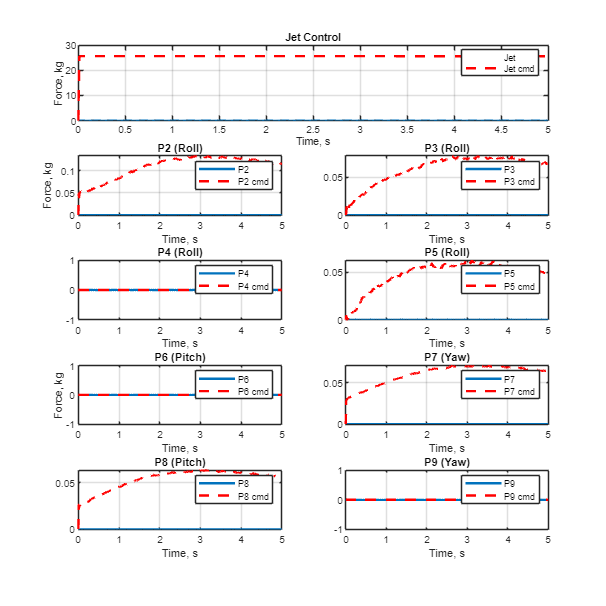

%% Plot control
figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

u_plot = u_hist / params.g;
u_cmd_plot = u_cmd_hist / params.g;

subplot(5,2,[1 2]); 
plot(tspan, u_plot(1,:), ...
    tspan, u_cmd_plot(1,:), 'r--');
title('Jet Control'); grid; 
xlabel('Time, s'); ylabel('Force, kg');
legend('Jet', 'Jet cmd');


% Roll Propellers
subplot(5,2,3); 
plot(tspan, u_plot(2,:), ...
    tspan, u_cmd_plot(2,:), 'r--'); 
% plot(tspan(1:end-1), u_cmd_plot(2,:)); 
title('P2 (Roll)'); grid;
xlabel('Time, s'); ylabel('Force, kg');
legend('P2', 'P2 cmd');

subplot(5,2,4); 
plot(tspan, u_plot(3,:), ...
    tspan, u_cmd_plot(3,:), 'r--'); 
% plot(tspan(1:end-1), u_cmd_plot(3,:)); 
title('P3 (Roll)'); grid; xlabel('Time, s'); 
legend('P3', 'P3 cmd');

subplot(5,2,5); 
plot(tspan, u_plot(4,:), ...
    tspan, u_cmd_plot(4,:), 'r--'); 
% plot(tspan(1:end-1), u_cmd_plot(4,:)); 
title('P4 (Roll)'); grid; xlabel('Time, s'); 
legend('P4', 'P4 cmd');

subplot(5,2,6); 
plot(tspan, u_plot(5,:), ...
    tspan, u_cmd_plot(5,:), 'r--'); 
% plot(tspan(1:end-1), u_cmd_plot(5,:));
title('P5 (Roll)'); grid; xlabel('Time, s'); 
legend('P5', 'P5 cmd');

% Verical Propellers
subplot(5,2,7); 
plot(tspan, u_plot(6,:), ...
    tspan, u_cmd_plot(6,:), 'r--'); 
title('P6 (Pitch)'); grid; xlabel('Time, s'); ylabel('Force, kg');
legend('P6', 'P6 cmd');

subplot(5,2,8); 
plot(tspan, u_plot(7,:), ...
    tspan, u_cmd_plot(7,:), 'r--'); 
title('P7 (Yaw)'); grid; xlabel('Time, s');
legend('P7', 'P7 cmd');

subplot(5,2,9); 
plot(tspan, u_plot(8,:), ...
    tspan, u_cmd_plot(8,:), 'r--'); 
title('P8 (Pitch)'); grid; xlabel('Time, s');
legend('P8', 'P8 cmd');

subplot(5,2,10); 
plot(tspan, u_plot(9,:), ...
    tspan, u_cmd_plot(9,:), 'r--'); 
title('P9 (Yaw)'); grid; xlabel('Time, s');
legend('P9', 'P9 cmd');


% set(groot, 'DefaultFigurePosition', [2000, 200, 200, 2000]);
% set(groot, 'DefaultFigurePosition', 'factory');    % use to reset size
set(findall(gcf,'type','line'),'linewidth', 2);

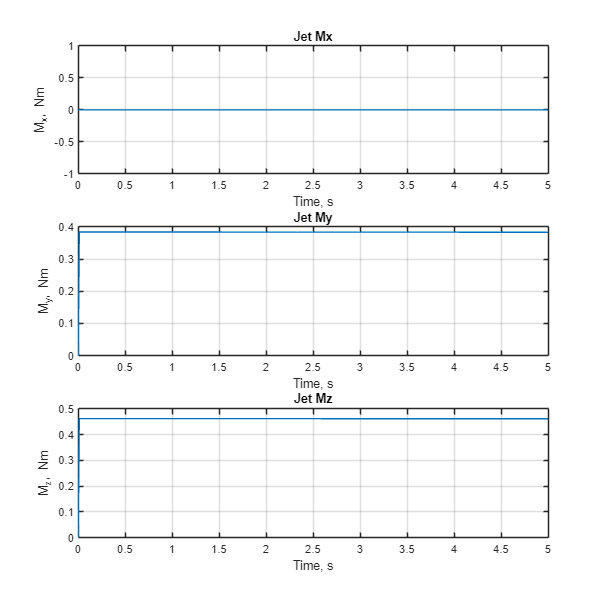

M_jet = params.Hm(:, 1) * u_cmd_hist(1,:);

%% Plot control
figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

subplot(3,1,1); 
plot(tspan, M_jet(1,:));
title('Jet Mx'); grid; 
xlabel('Time, s'); ylabel('M_x, Nm');

subplot(3,1,2); 
plot(tspan, M_jet(2,:));
title('Jet My'); grid; 
xlabel('Time, s'); ylabel('M_y, Nm');

subplot(3,1,3); 
plot(tspan, M_jet(3,:));
title('Jet Mz'); grid; 
xlabel('Time, s'); ylabel('M_z, Nm');

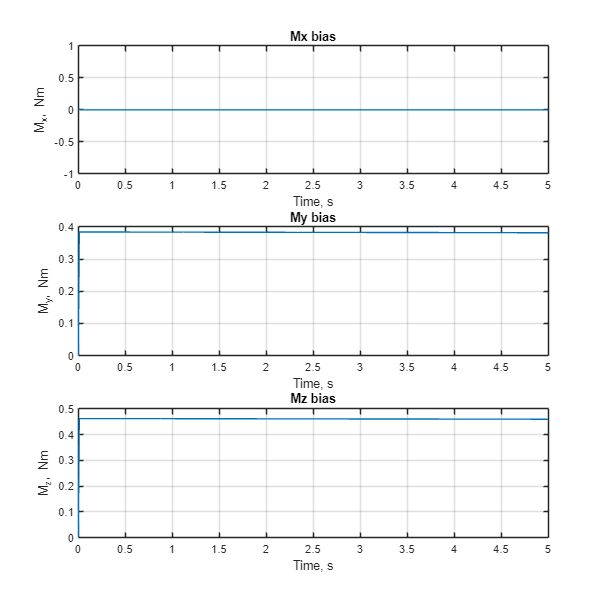

M_jet = M_bias_hist;

%% Plot control
figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

subplot(3,1,1); 
plot(tspan, M_jet(1,:));
title('Mx bias'); grid; 
xlabel('Time, s'); ylabel('M_x, Nm');

subplot(3,1,2); 
plot(tspan, M_jet(2,:));
title('My bias'); grid; 
xlabel('Time, s'); ylabel('M_y, Nm');

subplot(3,1,3); 
plot(tspan, M_jet(3,:));
title('Mz bias'); grid; 
xlabel('Time, s'); ylabel('M_z, Nm');

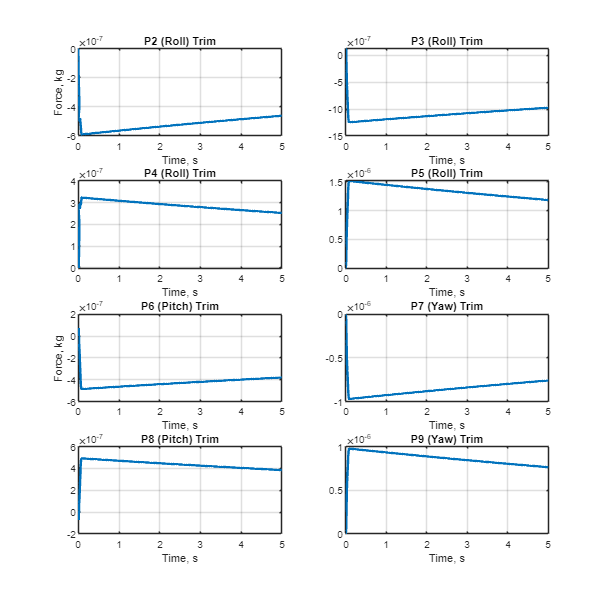

%% Plot control
figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

u_plot = u_trim_hist / params.g;

% Roll Propellers
subplot(4,2,1); 
plot(tspan, u_plot(1,:)); 
% plot(tspan(1:end-1), u_cmd_plot(2,:)); 
title('P2 (Roll) Trim'); grid;
xlabel('Time, s'); ylabel('Force, kg');
%legend('P2', 'P2 cmd');

subplot(4,2,2); 
plot(tspan, u_plot(2,:)); 
% plot(tspan(1:end-1), u_cmd_plot(3,:)); 
title('P3 (Roll) Trim'); grid; xlabel('Time, s'); 
% legend('P3', 'P3 cmd');

subplot(4,2,3); 
plot(tspan, u_plot(3,:)); 
% plot(tspan(1:end-1), u_cmd_plot(4,:)); 
title('P4 (Roll) Trim'); grid; xlabel('Time, s'); 
% legend('P4', 'P4 cmd');

subplot(4,2,4); 
plot(tspan, u_plot(4,:)); 
% plot(tspan(1:end-1), u_cmd_plot(5,:));
title('P5 (Roll) Trim'); grid; xlabel('Time, s'); 
% legend('P5', 'P5 cmd');

% Verical Propellers
subplot(4,2,5); 
plot(tspan, u_plot(5,:)); 
title('P6 (Pitch) Trim'); grid; xlabel('Time, s'); ylabel('Force, kg');
% legend('P6', 'P6 cmd');

subplot(4,2,6); 
plot(tspan, u_plot(6,:)); 
title('P7 (Yaw) Trim'); grid; xlabel('Time, s');
% legend('P7', 'P7 cmd');

subplot(4,2,7); 
plot(tspan, u_plot(7,:)); 
title('P8 (Pitch) Trim'); grid; xlabel('Time, s');
% legend('P8', 'P8 cmd');

subplot(4,2,8); 
plot(tspan, u_plot(8,:)); 
title('P9 (Yaw) Trim'); grid; xlabel('Time, s');
% legend('P9', 'P9 cmd');


% set(groot, 'DefaultFigurePosition', [2000, 200, 200, 2000]);
% set(groot, 'DefaultFigurePosition', 'factory');    % use to reset size
set(findall(gcf,'type','line'),'linewidth', 2);

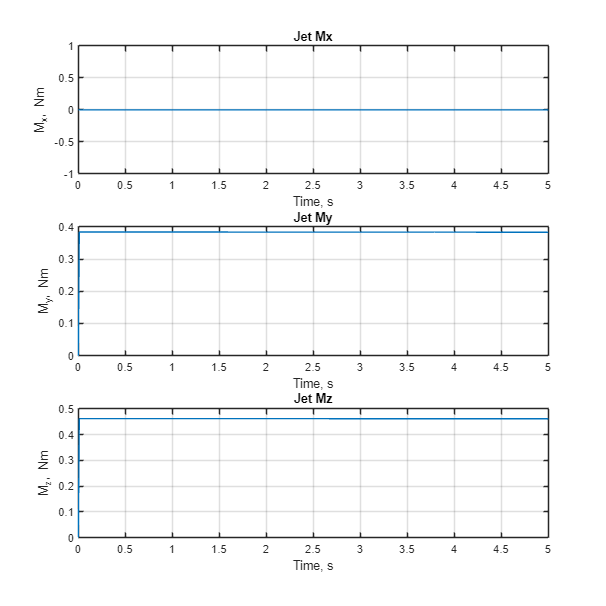

M_jet = params.Hm(:, 1) * u_cmd_hist(1,:);

%% Plot control
figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

subplot(3,1,1); 
plot(tspan, M_jet(1,:));
title('Jet Mx'); grid; 
xlabel('Time, s'); ylabel('M_x, Nm');

subplot(3,1,2); 
plot(tspan, M_jet(2,:));
title('Jet My'); grid; 
xlabel('Time, s'); ylabel('M_y, Nm');

subplot(3,1,3); 
plot(tspan, M_jet(3,:));
title('Jet Mz'); grid; 
xlabel('Time, s'); ylabel('M_z, Nm');

## STA State Plot

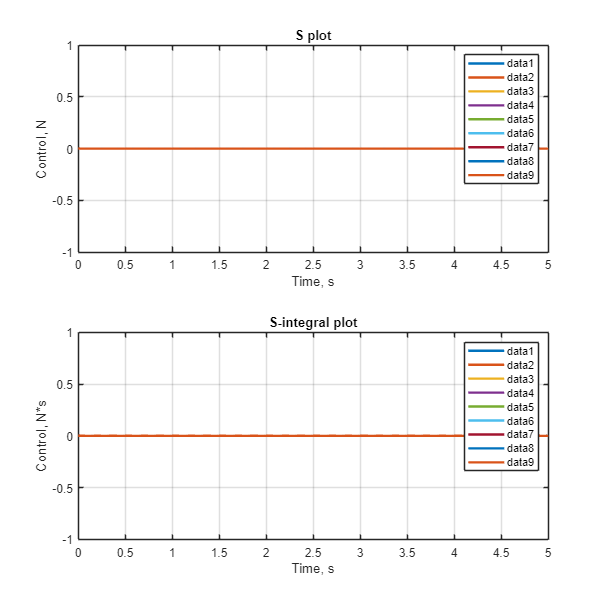

figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

subplot(2,1,1);
plot(tspan, s_hist);
title('S plot');
xlabel('Time, s'); ylabel('Control, N'); grid;
legend();

subplot(2,1,2);
plot(tspan, z2_hist);
title('S-integral plot');
xlabel('Time, s'); ylabel('Control, N*s'); grid;
legend();

% set(groot, 'DefaultFigurePosition', [2000, 200, 200, 2000]);
set(findall(gcf,'type','line'),'linewidth', 2);

## Functions

function dx = HopperDynGrav(x, u, param, A, B)
    dx = zeros(size(x));
    G = zeros(size(A,1),1);
    G(4:6) = Nw2(x(7:9)) * param.G;
    dx(1:12) = A*x(1:12) + B*u + G;
    dx(13) = -abs(u(1)) * param.beta;
end

function ds = HopperActDyn(s, uc, param, A, B)
    % Hopper Dynamic and Actuators dynamic
    % s = [x; u]
    nu = size(uc,1);
    x = s(1:end-nu); 
    u = s(end-nu+1:end,:);
    dx = HopperDynGrav(x, u, param, A, B);  % Hopper dynamoc
    du = actuator_dyn(u, uc, param.ctrl);        % Actuator dynamic
    ds = [dx; du];
end


function ds = HopperActDynNL(s, uc, param)
    % Hopper Dynamic and Actuators dynamic
    % s = [x; u]
    nu = size(uc,1);
    x = s(1:end-nu); 
    u = s(end-nu+1:end,:);
    dx = NL_HopperDyn(x, u, param);                % Hopper dynamic
    du = actuator_dyn(u, uc, param.ctrl);        % Actuator dynamic
    ds = [dx; du];
end


function xdot = NL_HopperDyn(x, u, param)
    % NL_HOPPERDYN_1 Summary of this function goes here
    %   Detailed explanation goes here
    % x(13) - State Vector 6DoF: px,py,pz, vx,vy,vz, roll, pitch,yaw,
    %       - wx, wy, wz, m
    % u(9)  - Control Vector: Fx,Fy,Fz, Mx,My,Mz
    % params - System Parameters: Jxx,Jyy,Jzz,Jxy,Jyz,Jxz,m,Cx,Cy,Cz,Cr,Cq,Cp,g,
    %       - beta, gamma, rho, h, d, k_quat

    %% State vector
    % r = x(1:3);           % position
    v = x(4:6);             % velocity
    a = x(7:9);             % Euler's angles
    w = x(10:12);           % angular velocity
    m = x(13);              % current mass
    
    %% Disturbances
    Fd = param.d(1:3);            % Disturbance Forces
    Md = param.d(4:6);            % Disturbance Moments
    %% Mass and Inertia matrices
    
    mdot = -abs(u(1)) * param.beta;
    rcg = mass_center_interpolate(x(13), param.mass, param.rcgs);
    [Hf, Hm] = ComponentForForces(param.geom, rcg);
    %% Control Forces
    uuu = [Hf; Hm] * u; 
    F = uuu(1:3);                       % Forces
    M = uuu(4:6);                       % Moments

    Jo = tensor_interpolation(m, param.mass, param.Inertia);
    Jdot = param.Jdot_mlt * mdot;                                            % debug
    
    Mass = diag([m, m, m]);
    %% Damping matrices
    Cv = param.Cv;
    Cw = param.Cw;
    %% DCM
    DCM = Nw2(a);                                    % inertial to body DCM
    %% Gravity
    G = param.gc * DCM * param.G;          % Get gravity in body frame    
    %% System of Equations 
    xdot = zeros(size(x,1), 1);                     % initialize
    xdot(1:3, 1)    = v;
    xdot(4:6, 1)    = -cross(w, v) + Mass \ (-Cv * v + F + Fd) + G;
    xdot(7:9, 1)    = Tw2(a) * w;
    xdot(10:12, 1)  = Jo \ (-cross(w, Jo*w)  - Cw*w - Jdot * w + M + Md);
    xdot(13, 1)     = mdot;
end

function [A, B] = jacobian_HopperODE(x, u, p)
    % BUILD_LSYS Summary of this function goes here
    %   Detailed explanation goes here
    % x - state vector for linearization
    % u - control vector
    % p - parameters
    
    %% Declare
    A = zeros(size(x,1));
    B = zeros(size(x,1), size(u,1));
    r = x(1:3);                     % coordinates
    v = x(4:6);                     % velocity
    eul0 = x(7:9);                  % angles
    w = x(10:12);                   % angular velocity
    %% Unpack parameters
    m = p.m;                % current mass
    Mass = diag([m, m, m]);
    Js = tensor_interpolation(m, p.mass, p.Inertia);
    rcg = mass_center_interpolate(m, p.mass, p.rcgs);
    [Hf, Hm] = ComponentForForces(p.geom, rcg);
    Cv = p.Cv;
    Cw = p.Cw;
    
    A11 = zeros(3,3);
    A12 = eye(3,3);
    A21 = zeros(3,3);
    A22 = -skew(w) + Mass \ (-Cv); % + Nrot * G; for linear system exclude gravity (to make system Linear)
    
    At = [A11, A12;
          A21, A22];
    
    A33 = zeros(3,3);
    A43 = zeros(3,3);
    A34 = Tw2(eul0);
    A44 = Js \ (-skew(w) * Js - Cw);
    Ar = [A33, A34;
          A43, A44];
    
    A = [At, zeros(6,6); 
        zeros(6,6), Ar];
    if p.grav_on > 0
        A(4:6,7:9) = grav_lin2(eul0, p.g);
    end
    %% Control
    B11 = zeros(3, 9);
    B21 = Mass \ Hf;
    Bt = [B11;
          B21];
    B31 = zeros(3,9);
    B41 = Js \ Hm;
    Br = [B31;
          B41];
    B = [Bt; Br];
end


function ref = reference(x, p, t, tstop, dt)
    ref = moveXup(x, p, t, tstop, dt);
    if t > tstop + 5
        ref = moveXdown(ref, p, t-tstop-5, 2.5*tstop, dt);
    end
end


function ref = traj(t, t_stop, x_ref)
    vxd = x_ref(4);
    vyd = 0.5;
    v_down = 0.2;
    pitch_d = x_ref(8);
    if t < t_stop
        ref = [vxd*t; 0;  0;
               vxd;   0;  0;
               0;  pitch_d; 0;
               0;     0;  0];
    elseif t_stop <= t && t < t_stop + 5
        ref = [vxd*t_stop; 0;  0;
               0;   0;  0;
               0;  pitch_d; 0;
               0;     0;  0];
    elseif t_stop+5 <= t && t < t_stop + 15
        ref = [vxd*t_stop; -vyd*(t-t_stop-5);  0;
               0;   -vyd;  0;
               0;  pitch_d; 0;
               0;     0;  0];
    elseif t_stop + 15 <= t && t < t_stop + 20
        ref = [vxd*t_stop; -vyd*(t_stop);  0;
               0;   0;  0;
               0;  pitch_d; 0;
               0;     0;  0];
    elseif t_stop + 20 <= t && t < t_stop + 70
        ref = [vxd*t_stop - v_down*(t - 30); -vyd*(t_stop);  0;
               -v_down;   0;  0;
               0;  pitch_d; 0;
               0;     0;  0];
    else
        ref = [0; -vyd*(t_stop);  0;
               0;   0;  0;
               0;  pitch_d; 0;
               0;     0;  0];
    end
end


function ref = ref_traj_generator(t_now, Ts, horizon, t_stop, x_ref)
    ref = zeros(horizon, 12);  % Assuming 12 state outputs
    for i = 1:horizon
        t_next = t_now + (i-1)*Ts;
        ref(i, :) = traj(t_next, t_stop, x_ref)';  % Some function of time
    end
end


% Saturation function
function y = sat(x, xlim)
    y = min(xlim(:,2), max(xlim(:,1), x));  % Saturation between [-1, 1]
end



%% Actuator Dynamic
function dudt = actuator_dyn(u, u_app, p)
    % Acting dynamic is T*u_dot + t1*u = u_smc
    % T = p.T
    % t1 = p.t1
    % u - current or previous control magnitude
    % u_smc - applied control
    dudt = (u_app - p.t1 .*u) ./ p.T;
end


function [u_cmd, dbg] = vtol_attitude_only_actuator_lqr_ctrl(x_hat, x_ref, params)
    eul = wrapToPi(x_hat(7:9));
    omg = x_hat(10:12);
    m   = x_hat(13);

    att_ref  = wrapToPi(x_ref(7:9));
    rate_ref = x_ref(10:12);

    att_err  = wrapToPi(eul - att_ref);
    rate_err = omg - rate_ref;
    err_r = [att_err; rate_err];

    % Fixed hover thrust
    u_cmd = zeros(9,1);
    u_cmd(1) = m * params.g;

    % Current geometry / CG-dependent moment map
    rcg = mass_center_interpolate(m, params.mass, params.rcgs);
    [~, Hm_cur] = ComponentForForces(params.geom, rcg);
    Hm_sub = Hm_cur(:,2:9);

    % Jet bias moment
    M_jet = Hm_cur(:,1) * u_cmd(1);

    % Feedforward trim from known jet moment
    u_trim_ff = -pinv(Hm_sub) * M_jet;

    % LQR correction
    du_att = -params.ctrl.K_att_u * err_r;

    % Total attitude-prop command
    u_raw = u_trim_ff + du_att;

    % Hard clip for now
    u_cmd(2:9) = max(params.ctrl.ulim(2:9,1), min(params.ctrl.ulim(2:9,2), u_raw));

    dbg.err_r     = err_r;
    dbg.du_att    = du_att;
    dbg.u_trim_ff = u_trim_ff;
    dbg.M_jet     = M_jet;
    dbg.M_ach     = Hm_sub * u_cmd(2:9);
end

function y = softsat(x, xmin, xmax)
    xmid = 0.5 * (xmax + xmin);
    xamp = 0.5 * (xmax - xmin);
    y = xmid + xamp .* tanh((x - xmid) ./ max(xamp, 1e-6));
end

function trim_state = update_trim_estimator(trim_state, x_hat, x_ref, params)
    att_err  = wrapToPi(x_hat(7:9) - x_ref(7:9));
    rate_err = x_hat(10:12) - x_ref(10:12);

    % Adapt only when rates are small enough
    rate_gate = all(abs(rate_err) < deg2rad([0.8; 0.8; 0.8]));
    att_gate  = all(abs(att_err)  < deg2rad([8; 8; 8])/8);

    if rate_gate && att_gate
        e_trim = att_err;

        % deadzone on small errors
        dz = deg2rad([0.05; 0.05; 0.05]);
        e_eff = sign(e_trim) .* max(abs(e_trim) - dz, 0);

        Mdot_hat = params.ctrl.trim_ki * e_eff ...
                 - params.ctrl.trim_leak * trim_state.M_bias_hat;
    else
        % only leak when far from equilibrium
        Mdot_hat = -params.ctrl.trim_leak * trim_state.M_bias_hat;
    end

    trim_state.M_bias_hat = trim_state.M_bias_hat + params.ctrl.dt * Mdot_hat;

    Hm_sub = params.Hm(:,2:9);
    trim_state.u_trim = pinv(Hm_sub) * (-trim_state.M_bias_hat);

    trim_state.u_trim = max(-params.ctrl.trim_umax, min(params.ctrl.trim_umax, trim_state.u_trim));
end